**Essentials of Ultrasound Imaging: Lecture 4**

**GUI: Fourier  Transform Calculator**

**Author: Joseph Greene**

**Reference: Chapter 2.2, Fourier Transform/ Appendix A**

Brief Description: In this Live Editor, we will discuss how we may depict the Fourier Transform of a signal.

Inputs: Signal type, Tone Burst Frequency, Gaussian Variance, Super-Gaussian Variance, Super-Gaussian Order, Delta Center Time

Outputs: Frequency Spectrum (Graph)

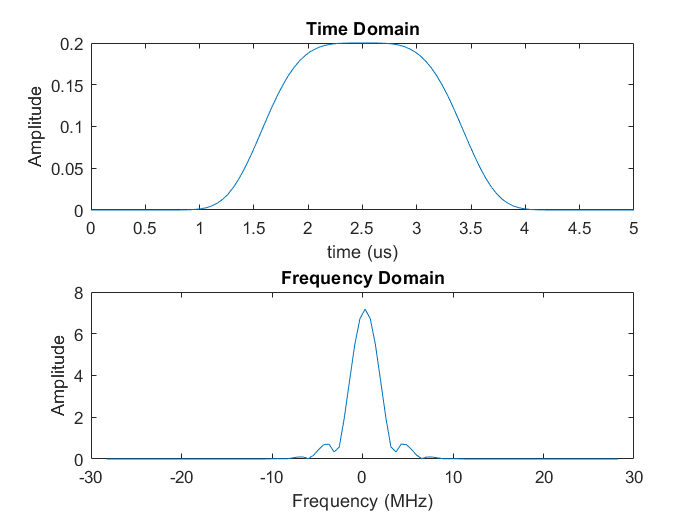

%%%%%%%%%%%%
%User Inputs
%%%%%%%%%%%%
%{
 Choose a Original Signal
    0: Tone Burst
    1: Gaussian
    2: Super-Gaussian
    3: Delta
%}
Signal_type = 2;

%Tone Burst Properties
freq = 10; %MHz

%Gaussian Properties
var = 5; %Sigma squared in gaussian formula

%Super-Gaussian Properties
var_SG = 5;
order = 2;

%Delta
center = 2.5; %Center in time - put value between 0 and 5

n = 100; %Number of samples in time domain
t = linspace(0,5,n); %Time Domain Range in us


%%%%%%%%%%%%%%%%
%Generate Graphs
%%%%%%%%%%%%%%%%
%Calculate frequency domain using the fact that dx*du = 2*pi
F = linspace(-pi/(1/(0.1*n-1)),pi/(1/(0.1*n-1)),n); %Freq domain sampling  
%Define useful equations
Ft = @(x) fftshift(fft(x,2*n)); %1D Fourier transform. The second argument pads original signal to reduce artifacts by circulant nature of FFT.
S = @(f) sin(f*t); %Tone Burst
G = @(v) 1*exp(-(t-2.5).^2./(v)); %Gaussian centered at 2.5 us
SG = @(v,o) ((1*exp(-(t-2.5).^(2*o))./(v))); %Standard gaussian to the o-th power

if Signal_type == 0
    signal = S(freq);
    transform = Ft(signal);
    
elseif Signal_type == 1
    signal = G(var);
    transform = Ft(signal);
    
elseif Signal_type == 2
     signal = SG(var_SG, order);
     transform = Ft(signal);
     
else
    t = round(center/5*(n-1))+1; %Round to closest spot in graph
    signal = zeros(size(T)); %Define zeros
    signal(t) = 1; %Assign single point to one
    transform = Ft(signal);
    
end

figure
subplot(2,1,1)
plot(t,signal)
title('Time Domain')
xlabel('time (us)')
ylabel('Amplitude')

subplot(2,1,2)
plot(F,abs(transform((round(n/2)+1):(round(3*n/2))))) %Clip transform to remove padding
title('Frequency Domain')
xlabel('Frequency (MHz)')
ylabel('Amplitude')